# Power generation and Energy Budget LoLaSat

## A. Power Generated with different attitudes Vs Beta angle at multiple altitudes

### 1. Calculation at multiple altitudes, case for orbital pointing mode

First, we will see what is the generated power at different altitudes, with the variation of the beta angle.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The peak power generation with a solar cell string (7 cells) is calculated to be 7.08W.

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=90%, *maybe too optimistic*.

The difference here is the pointing mode, that is set to 1 in this section, because it corresponds to the orbital (nadir) pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.90;
Pcell = 2.32*0.436; % Peak power generated by a cell, no conversion efficiency
PsaX = 7 * Pcell;   %Peak power generation +Z side[W] 8 solar cells
Psa_X = 0*Pcell;    %Peak power generation -Z side[W] 8 solar cells
PsaY = 7 * Pcell;   %Peak power generation +Z side[W] 8 solar cells
Psa_Y= 7 * Pcell;   %Peak power generation -Z side[W] 8 solar cells
eff_ACU = 0.85;     %efficiency MPPT conversion
P_eps = 0.1;        %internal power consumption EPS [W]
angle_roll = pi/4;  %Rotated angle in roll for MODE 9

%Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 1;   %"sun-aero" pointing mode
% 1: "orbital" Reference quaternion is aligned with ORF. 

for j=1:2
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    TimeStep = 5;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagatorLoLaSat');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_nadir(j,i)=mean(Pcollected);
        B_nadir(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude_LLSat.mat'

        %save('power_from_b_alt_mode1_LLSat.mat','B_nadir','Pav_nadir')  
        %load('power_from_b_alt_mode1_LLSat.mat') %if we don't want to run the whole simulation again
        Pav=Pav_nadir;
        B=B_nadir;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

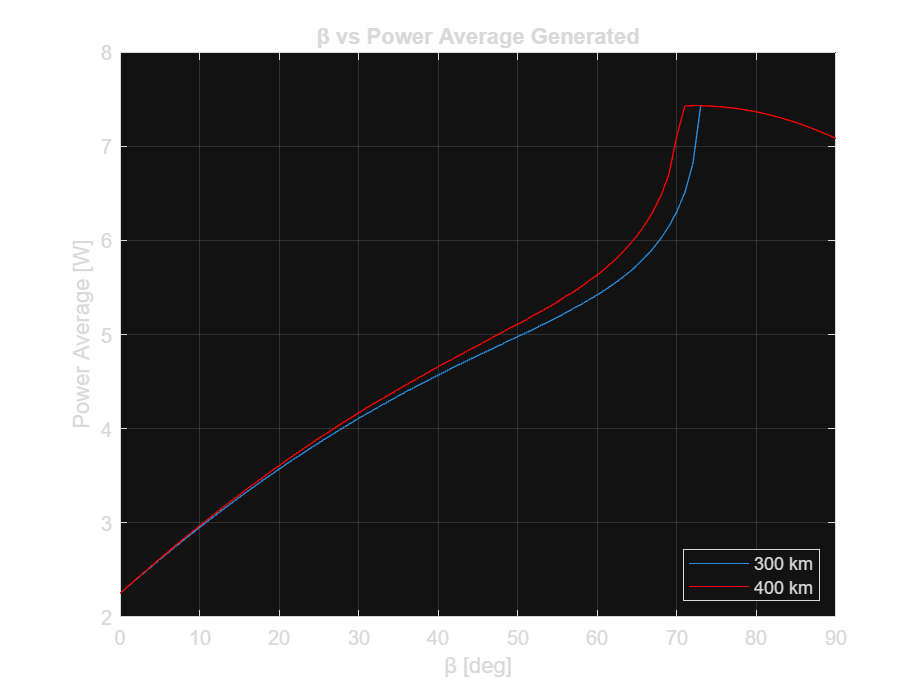

%Pav1=10:0.1:40;
Pav1=0:0.1:15;
B1 = interp1(Pav(1,:),B(1,:),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,:),B(2,:),Pav1);     %Interpolation for altitude 400km, etc

figure(1)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        legend('300 km','400 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        %set(gcf,'position',[x0,y0,width,height])
        set(gcf,'position',[50,100,800,400])
        grid on 

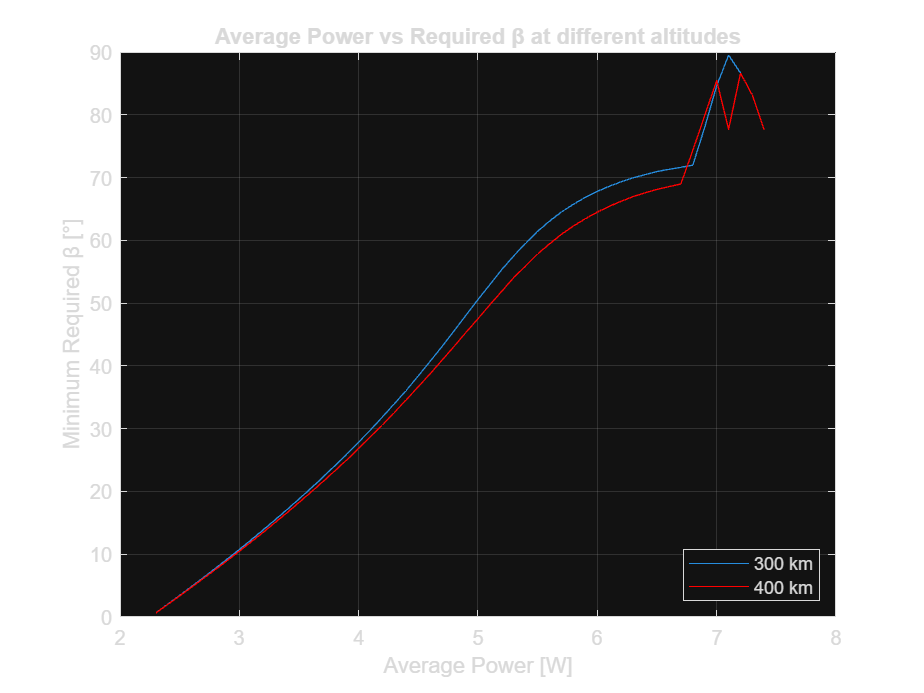

figure(2)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        legend('300 km','400 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Minimum Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.

### 2. Calculation at multiple altitudes, case for sun-aero pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the sun pointing with the constraint of exposing the minimum surface in the direction of velocity.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated in the same way as the previous section.

The same procedure is done for several orbits with different altitudes. 

The difference here is the pointing mode, that is set to 2 in this section, because it corresponds to the sun pointing- minimum aero-drag pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.90;
Pcell = 2.32*0.436; % Peak power generated by a cell, no conversion efficiency
PsaX = 7 * Pcell;   %Peak power generation +Z side[W] 8 solar cells
Psa_X = 0*Pcell;    %Peak power generation -Z side[W] 8 solar cells
PsaY = 7 * Pcell;   %Peak power generation +Z side[W] 8 solar cells
Psa_Y= 7 * Pcell;   %Peak power generation -Z side[W] 8 solar cells
eff_ACU = 0.85;     %efficiency MPPT conversion
P_eps = 0.1;        %internal power consumption EPS [W]
angle_roll = pi/4;  %Rotated angle in roll for MODE 9
t=0;
%Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 2;   %"sun-aero" pointing mode

for j=1:2
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 5;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagatorLoLaSat');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_saero(j,i)=mean(Pcollected);
        B_saero(j,i)=mean(beta);
    end
end

Program interruption (Ctrl-C) has been detected.

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude_LLSat.mat'

        %save('power_from_b_alt_mode2_LLSat.mat','B_saero','Pav_saero')  
        load('power_from_b_alt_mode2_LLSat.mat') %if we don't want to run the whole simulation again
        Pav = Pav_saero;
        B = B_saero;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

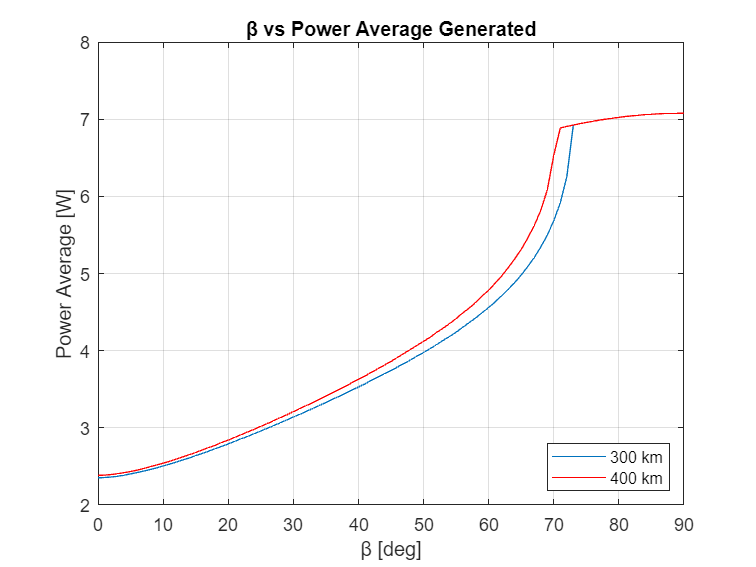

Pav1=0.1:0.1:15;
B1 = interp1(Pav(1,:),B(1,:),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,:),B(2,:),Pav1);     %Interpolation for altitude 400km, etc

close all

figure(3)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        legend('300 km','400 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        set(gcf,'position',[50,100,800,400])
        grid on 

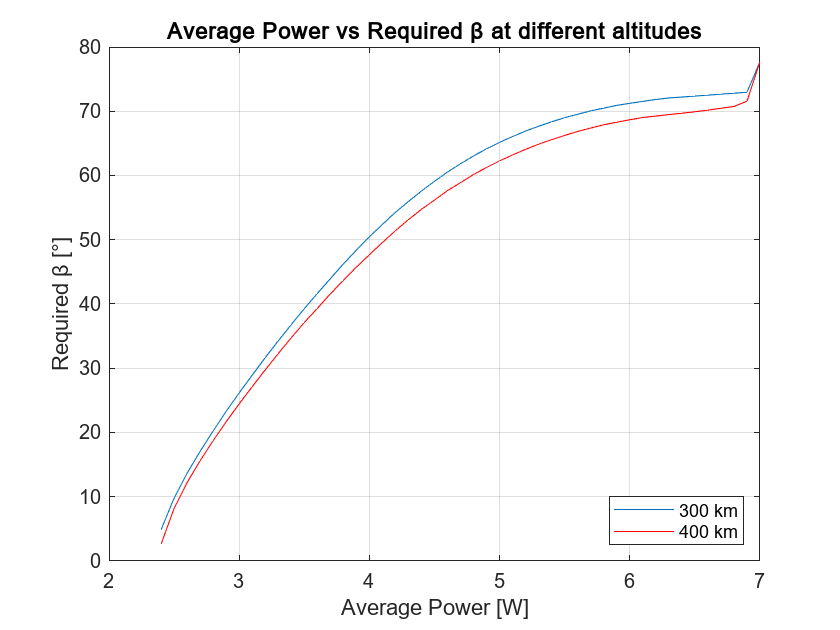

figure(4)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        legend('300 km','400 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.

### 3. Calculation at multiple altitudes, case for sun pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the sun pointing mode.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated in a similar way to the previous cases.

The same procedure is done for several orbits with different altitudes.

The difference here is the pointing mode, that is set to 3 in this section, because it corresponds to the sun pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.90;
Pcell = 2.32*0.436; % Peak power generated by a cell, no conversion efficiency
PsaX = 7 * Pcell;   %Peak power generation +X side[W] 8 solar cells
Psa_X = 0*Pcell;    %Peak power generation -X side[W] 8 solar cells
PsaY = 7 * Pcell;   %Peak power generation +Y side[W] 8 solar cells
Psa_Y= 7 * Pcell;   %Peak power generation -Y side[W] 8 solar cells
eff_ACU = 0.85;     %efficiency MPPT conversion
P_eps = 0.1;        %internal power consumption EPS [W]
angle_roll = pi/4;  %Rotated angle in roll for MODE 9

%Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 3;   %"sun pointing" Reference quaternion is such that z is aligned with the sun direction to maximize the power generation and x is aligned as best as possible with the velocity direction.

for j=1:2
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 5;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagatorLoLaSat');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_sun(j,i)=mean(Pcollected);
        B_sun(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude_LLSAT.mat'

        %save('power_from_b_alt_mode3_LLSAT.mat','B_sun','Pav_sun')  
        %load('power_from_b_alt_mode3_LLSAT.mat') %if we don't want to run the whole simulation again
        %Average power assuming a rotation of 45 degrees
        %Pav = Pav_sun*sqrt(2); 
        Pav = Pav_sun; 
        B = B_sun;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

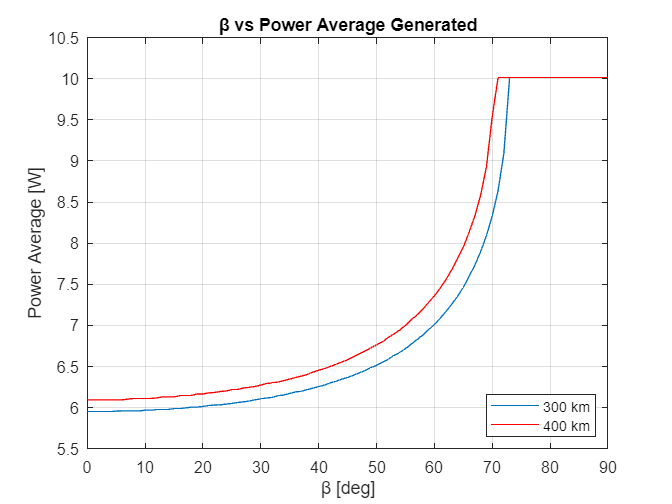

close all

figure(5)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        legend('300 km','400 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        set(gcf,'position',[50,100,800,400])
        grid on 

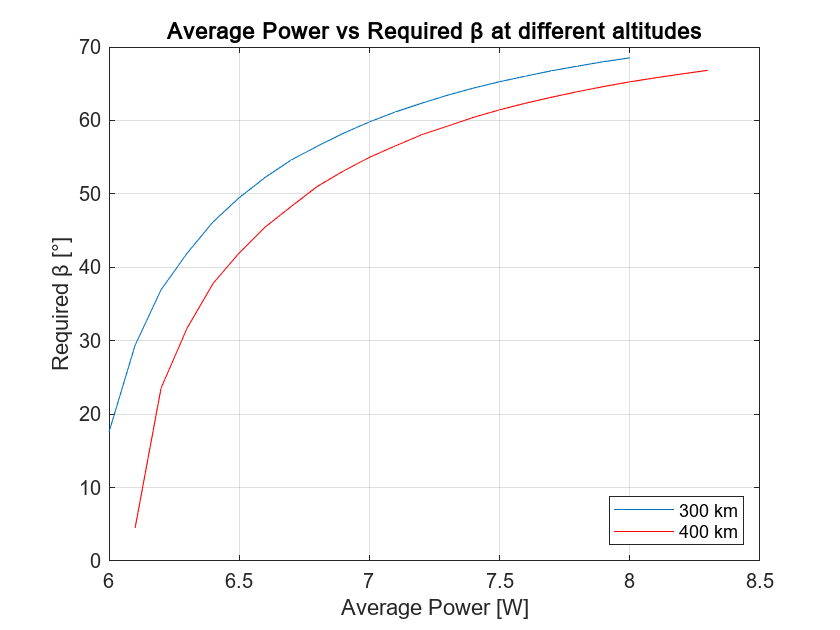

Pav1=0.1:0.1:15;
%Pav1=0:0.1:10.5;
B1 = interp1(Pav(1,1:70),B(1,1:70),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,1:68),B(2,1:68),Pav1);     %Interpolation for altitude 400km, etc

figure(6)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        legend('300 km','400 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.

### 4. Calculation at multiple altitudes, case for sun-roll pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the pointing mode, with a roll of 45 degrees to maximize power generation.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated in the same way as the previous section.

The same procedure is done for several orbits with different altitudes. 

The difference here is the pointing mode, that is set to 9 in this section, because it corresponds to the sun-roll pointing mode.

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.90;
Pcell = 2.32*0.436; % Peak power generated by a cell, no conversion efficiency
PsaX = 7 * Pcell;   %Peak power generation +Z side[W] 8 solar cells
Psa_X = 0*Pcell;    %Peak power generation -Z side[W] 8 solar cells
PsaY = 7 * Pcell;   %Peak power generation +Z side[W] 8 solar cells
Psa_Y= 7 * Pcell;   %Peak power generation -Z side[W] 8 solar cells
eff_ACU = 0.85;     %efficiency MPPT conversion
P_eps = 0.1;        %internal power consumption EPS [W]
angle_roll = pi/4;  %Rotated angle in roll for MODE 9

%Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 9;   %"sun-roll" pointing mode

for j=1:2
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 5;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagatorLoLaSat');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_sa_roll(j,i)=mean(Pcollected);
        B_sa_roll(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude_LLSat.mat'

        %save('power_from_b_alt_mode9_LLSat.mat','B_sa_roll','Pav_sa_roll')  
        load('power_from_b_alt_mode9_LLSat.mat') %if we don't want to run the whole simulation again
        Pav = Pav_sa_roll;
        B = B_sa_roll;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

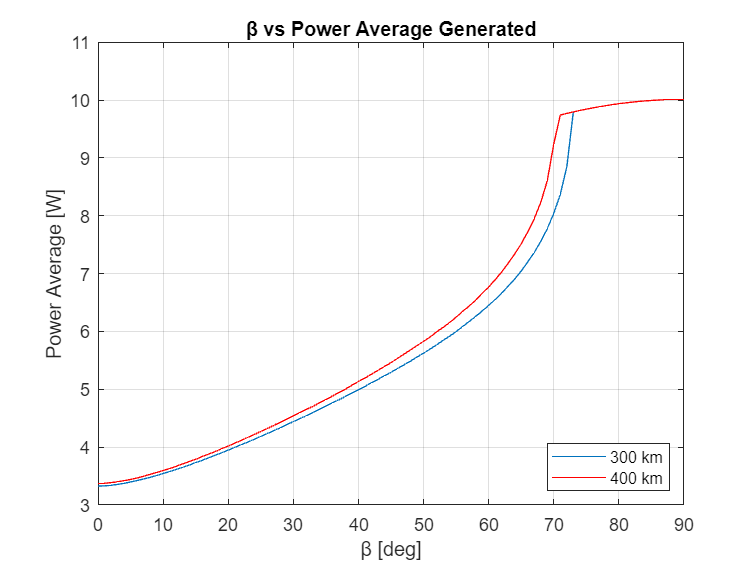

Pav1=0.1:0.1:15;
B1 = interp1(Pav(1,:),B(1,:),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,:),B(2,:),Pav1);     %Interpolation for altitude 400km, etc

close all

figure(7)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        legend('300 km','400 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        set(gcf,'position',[50,100,800,400])
        grid on 

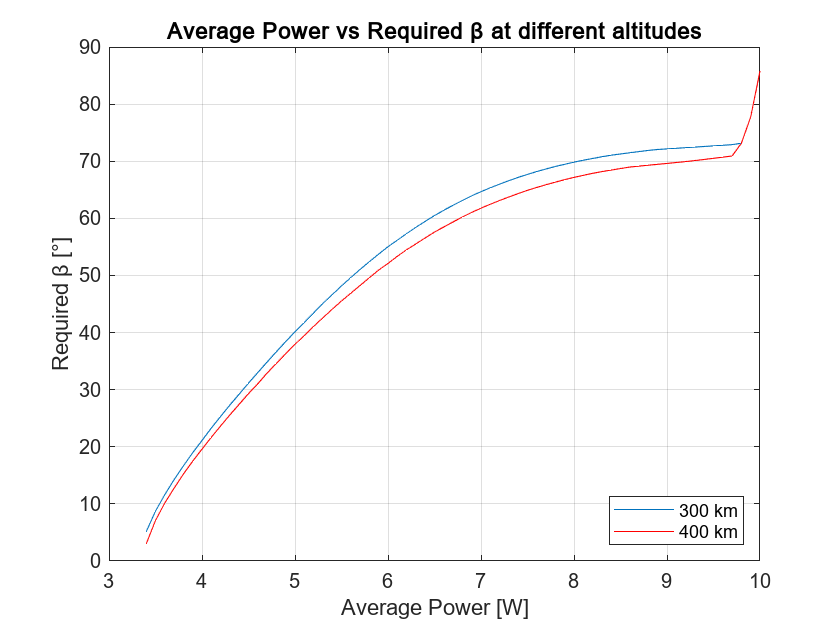

figure(8)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        legend('300 km','400 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.

### 5. Calculation at multiple altitudes, case for sun pointing mode WITH a rotation of 45 degrees

Now, we will see what is the generated power at different altitudes, with the variation of the beta angle of the sun pointing mode.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated in a similar way to the previous cases.

The same procedure is done for several orbits with different altitudes.

The difference here is the pointing mode, that is set to 10 in this section, because it corresponds to the sun pointing mode.

clear all
close all

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

angle_roll = pi/4;
%eff_Psa=0.90;
Pcell = 2.32*0.436; % Peak power generated by a cell, no conversion efficiency
PsaX = 7 * Pcell;   %Peak power generation +X side[W] 8 solar cells
Psa_X = 0*Pcell;    %Peak power generation -X side[W] 8 solar cells
PsaY = 7 * Pcell;   %Peak power generation +Y side[W] 8 solar cells
Psa_Y= 7 * Pcell;   %Peak power generation -Y side[W] 8 solar cells
eff_ACU = 0.85;     %efficiency MPPT conversion
P_eps = 0.1;        %internal power consumption EPS [W]
angle_roll = pi/4;  %Rotated angle in roll for MODE 9

%Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

%POINTING MODE
MODE = 10;   %"sun pointing" Reference quaternion is such that z is aligned with the sun direction to maximize the power generation and x is aligned as best as possible with the velocity direction.

for j=1:1
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 5;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagatorLoLaSat');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav_sun_roll(j,i)=mean(Pcollected);
        B_sun_roll(j,i)=mean(beta);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude_LLSAT.mat'

        %save('power_from_b_alt_mode10_LLSAT.mat','B_sun_roll','Pav_sun_roll')  
        %load('power_from_b_alt_mode10_LLSAT.mat') %if we don't want to run the whole simulation again
        %Average power assuming a rotation of 45 degrees
        Pav = Pav_sun_roll; 
        B = B_sun_roll;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

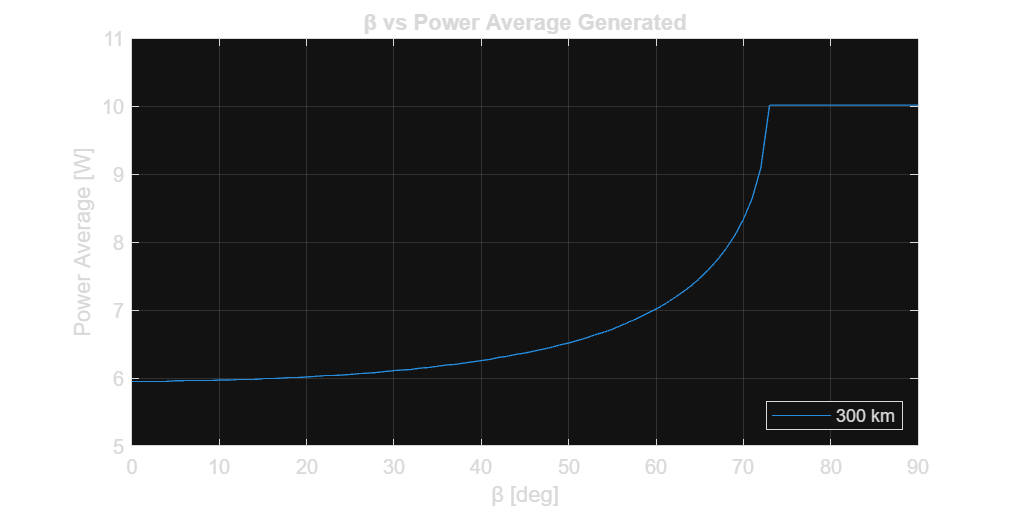

close all

figure(9)
%set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        %plot(B(2,:),Pav(2,:),'r')
        %legend('300 km','400 km')
        legend('300 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        set(gcf,'position',[50,100,800,400])
        grid on 

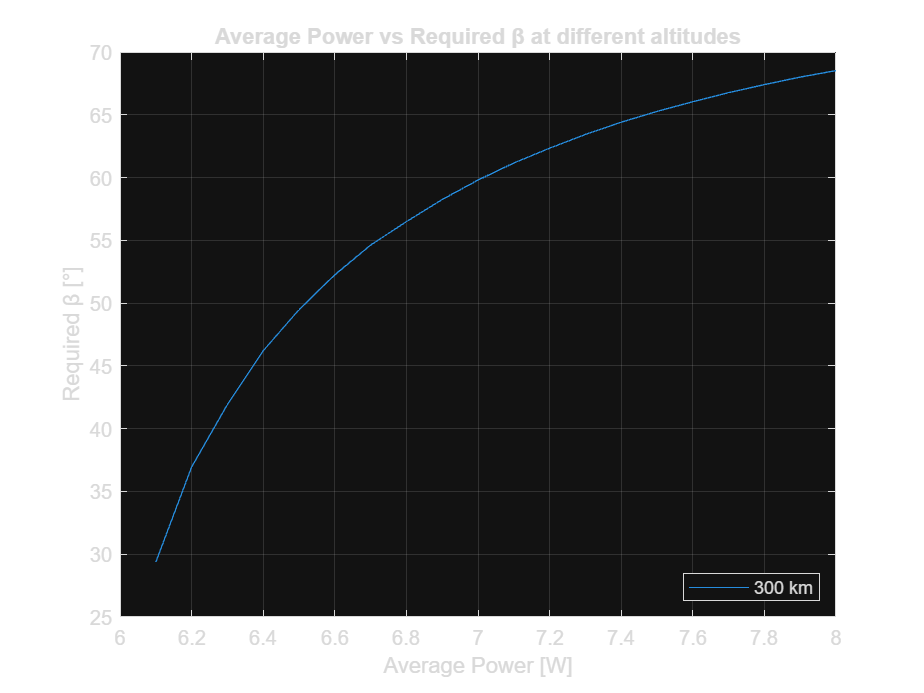

Pav1=6.0:0.1:8.9;
%Pav1=0:0.1:10.5;
x=Pav(1,21:70);
v=B(1,21:70);
B1 = interp1(x,v,Pav1);     %Interpolation for altitude 300km
%B1 = interp1(Pav(1,1:70),B(1,1:70),Pav1);     %Interpolation for altitude 300km
%B2 = interp1(Pav(2,1:68),B(2,1:68),Pav1);     %Interpolation for altitude 400km, etc

figure(10)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        %plot(Pav1,B2,'r')
        %legend('300 km','400 km')
        legend('300 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.

### 6. Calculation at multiple altitudes, case for intermediate between sun and sun-aero pointing mode

Now, we will see what is the generated power at different altitudes, with the variation of the rotation betwen the sun pointing mode and the sun-aero pointing mode.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated in a similar way to the previous cases.

The same procedure is done for several orbits with different altitudes.

The difference here is:

a) the pointing mode, a new pointing mode #11 in this section, because it corresponds to an intermediate the sun pointing mode and sun-aero

b) no variation of beta angle, beta angle is fixed at 0 degrees, because this is the interesting case (worst case)

clear all
close all

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

%eff_Psa=0.90;
Pcell = 2.32*0.436; % Peak power generated by a cell, no conversion efficiency
PsaX = 7 * Pcell;   %Peak power generation +X side[W] 8 solar cells
Psa_X = 0*Pcell;    %Peak power generation -X side[W] 8 solar cells
PsaY = 7 * Pcell;   %Peak power generation +Y side[W] 8 solar cells
Psa_Y= 7 * Pcell;   %Peak power generation -Y side[W] 8 solar cells
eff_ACU = 0.85;     %efficiency MPPT conversion
P_eps = 0.1;        %internal power consumption EPS [W]
angle_roll = pi/4;  %Rotated angle in roll for MODE 9

%Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=2;        %percentage of rotation from 0% (sun-aero) to 100% (sun)
maxRAAN=90;
%N=maxRAAN/paso;
N = 100/paso;

%POINTING MODE
MODE = 11;   %"sun pointing" Reference quaternion is such that z is aligned with the sun direction to maximize the power generation and x is aligned as best as possible with the velocity direction.
load('LLSat_3U.mat');
LLSataero.T = SNAP_aeromodel.T;
LLSataero.El = SNAP_aeromodel.Az;
LLSataero.Az = SNAP_aeromodel.El;
LLSataero.Tx = SNAP_aeromodel.T_x;
LLSataero.Ty = SNAP_aeromodel.T_y;
LLSataero.Tz = SNAP_aeromodel.T_z;
LLSataero.av_density_vs_alt = SNAP_aeromodel.av_density_vs_alt;
LLSataero.alt_range = SNAP_aeromodel.alt_range;
LLSataero.A_drag = SNAP_aeromodel.A_drag;


for j=1:2
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 5;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        %orbit.O = (i-1)*paso;
        t = (i-1)/N;
        %RAAN(i)= orbit.O ;
        Power=sim('powerfrompropagatorLoLaSat');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        %beta = getdatasamples(Power.beta,(1:length(time)));
        A_drag = getdatasamples(Power.A_drag,(1:length(time)));
        Pav_slerp(j,i)=mean(Pcollected);
        f_slerp(j,i)=t;
        Area_drag(j,i)=median(A_drag);
    end
end

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude_LLSAT.mat'

        %save('power_from_b_alt_mode11_LLSAT.mat','f_slerp','Pav_slerp', 'Area_drag')  
        %load('power_from_b_alt_mode11_LLSAT.mat') %if we don't want to run the whole simulation again
        %Average power assuming a rotation of 45 degrees
        Pav = Pav_slerp; 
        f = f_slerp;
        %Area_drag=Area_drag;

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

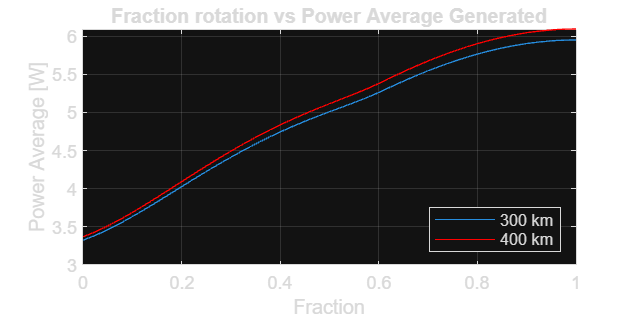

close all

figure(11)
%set(gcf,'color','w');
        plot(f(1,:),Pav(1,:))
        hold on;
        plot(f(2,:),Pav(2,:),'r')
        legend('300 km','400 km')
        legend('Location','southeast')
        title('Fraction rotation vs Power Average Generated')
        xlabel('Fraction')
        ylabel('Power Average [W]')
        set(gcf,'position',[50,100,800,400])
        grid on 

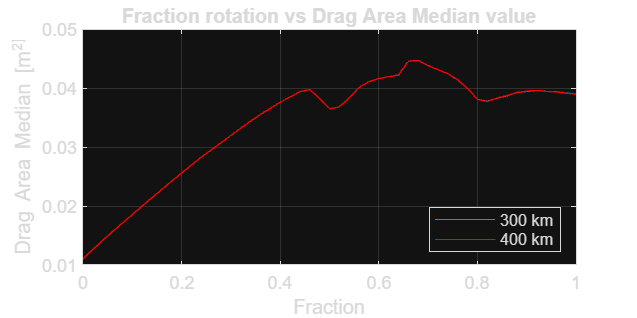

figure(12)
%set(gcf,'color','w');
        plot(f(1,:),Area_drag(1,:))
        hold on;
        plot(f(2,:),Area_drag(2,:),'r')
        legend('300 km','400 km')
        legend('Location','southeast')
        title('Fraction rotation vs Drag Area Median value')
        xlabel('Fraction')
        ylabel('Drag Area Median [m^2]')
        set(gcf,'position',[50,100,800,400])
        grid on 

        
        Pav1=3.4:0.1:4.7;
% B1 = interp1(Pav(1,1:70),B(1,1:70),Pav1);     %Interpolation for altitude 300km
% B2 = interp1(Pav(2,1:68),B(2,1:68),Pav1);     %Interpolation for altitude 400km, etc
% 
% figure(12)
%% set(gcf,'color','w');
%         plot(Pav1,B1)   
%         grid on
%         hold on;
%         plot(Pav1,B2,'r')
%         legend('300 km','400 km')
%         legend('Location','southeast')
%         title('Average Power vs Required β at different altitudes')
%         xlabel('Average Power [W]')
%         ylabel('Required β [°]')
%         %ylim([0,22])
%         grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed.

## TESTING

What happens when t=0.7?

clear all
close all

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

%eff_Psa=0.90;
Pcell = 2.32*0.436; % Peak power generated by a cell, no conversion efficiency
PsaX = 7 * Pcell;   %Peak power generation +X side[W] 8 solar cells
Psa_X = 0*Pcell;    %Peak power generation -X side[W] 8 solar cells
PsaY = 7 * Pcell;   %Peak power generation +Y side[W] 8 solar cells
Psa_Y= 7 * Pcell;   %Peak power generation -Y side[W] 8 solar cells
eff_ACU = 0.85;     %efficiency MPPT conversion
P_eps = 0.1;        %internal power consumption EPS [W]
angle_roll = pi/4;  %Rotated angle in roll for MODE 9
att.offset_axis = [0; 1; 0];    %error axis for MODE 9 only
att.offset_angle = 15*pi/180;   %error angle for MODE 9 only

%Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=10;        %percentage of rotation from 0% (sun-aero) to 100% (sun)
maxRAAN=90;
%N=maxRAAN/paso;
N = 100/paso;

%POINTING MODE
MODE = 11;   %"sun pointing" Reference quaternion is such that z is aligned with the sun direction to maximize the power generation and x is aligned as best as possible with the velocity direction.

orbit.a = (6371+200+1*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
TimeStep = 5;        %fixed-step size in solver, Default time step=0.25
Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
N_orbits = 5;           %number of orbits to be simulated
%Time spent performing the simulation in seconds (one orbit is ~5400 s):
t_sim = N_orbits*Torbit;
load('LLSat_3U.mat');
LLSataero.T = SNAP_aeromodel.T;
LLSataero.El = SNAP_aeromodel.Az;
LLSataero.Az = SNAP_aeromodel.El;
LLSataero.Tx = SNAP_aeromodel.T_x;
LLSataero.Ty = SNAP_aeromodel.T_y;
LLSataero.Tz = SNAP_aeromodel.T_z;
LLSataero.av_density_vs_alt = SNAP_aeromodel.av_density_vs_alt;
LLSataero.alt_range = SNAP_aeromodel.alt_range;
LLSataero.A_drag = SNAP_aeromodel.A_drag;
    %for i=1:N+1
    j=1;
    for i=1:1
        %orbit.O = (i-1)*paso;
        t = (i-1)/10;
        Power=sim('powerfrompropagatorLoLaSat');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        %beta = getdatasamples(Power.beta,(1:length(time)));
        A_drag = getdatasamples(Power.A_drag,(1:length(time)));

        Pav_slerp(j,i)=mean(Pcollected);
        f_slerp(j,i)=t;
        Area_drag(j,i)=median(A_drag);
    end